clc;
clear;
close all;

syms L S theta1 theta2 theta3 a x_c y_c

r_base = 290; %(mm)
r_plat = 130; 

%Point B centr of base
B = [r_base*sqrt(3)/2;r_base*sqrt(3)/2;0];

%Point C centre of platform
C = [x_c; y_c; 0];


%test variables
S_val = 170;
L_val = 130;
x_c_val = r_base*sqrt(3)/2;
y_c_val = r_base*sqrt(3)/2;
a_val = 0;

%FIRST LEG
%calculate the point M1
PB1 = [0;0;0];

M1 = PB1 + [S*cos(theta1);S*sin(theta1);0]

$$M1 = \left(\begin{array}{c} S\,\cos\left(\theta_{1}\right)\\ S\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$


%BPP1 = Rbc*CPP1 + BC
CPP1 = [-r_plat*cos(pi/6);-r_plat*sin(pi/6);0];
BC = C-B;
%rot
Rbc = [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
BPP1 = Rbc*CPP1 + BC;

%calculate point PP1 (%BPP1-BPB1)
PP1 = BPP1 - (PB1-B)

$$PP1 = \left(\begin{array}{c} x_{c}+65\,\sin\left(a\right)-65\,\sqrt{3}\,\cos\left(a\right)\\ y_{c}-65\,\cos\left(a\right)-65\,\sqrt{3}\,\sin\left(a\right)\\ 0 \end{array}\right)$$


%psi
psi1 = simplify(atan2(PP1(2,1)-M1(2,1), PP1(1,1)- M1(1,1)))

$$psi1 = \text{atan2}\left(y_{c}-65\,\cos\left(a\right)-65\,\sqrt{3}\,\sin\left(a\right)-S\,\sin\left(\theta_{1}\right),x_{c}+65\,\sin\left(a\right)-65\,\sqrt{3}\,\cos\left(a\right)-S\,\cos\left(\theta_{1}\right)\right)$$


%phi
phi1 = a + pi/6;
c = atan2(y_c-r_plat*sin(phi1),x_c-r_plat*cos(phi1));
acos_arg = (S^2 - L^2 + (x_c - r_plat * cos(phi1))^2 + (y_c - r_plat * sin(phi1))^2) / ...
           (2 * S * sqrt((x_c - r_plat * cos(phi1))^2 + (y_c - r_plat * sin(phi1))^2));
d = acos(acos_arg);

%phi
phi1_val = subs(phi1, a, a_val);

%theta1
theta1_1 = subs(c+d,[y_c x_c a S L],[x_c_val y_c_val a_val S_val L_val]);
theta1_2 = subs(c-d,[y_c x_c a S L],[x_c_val y_c_val a_val S_val L_val]);
double(theta1_1)

ans = 1.5143

double(theta1_2)

ans = 0.3475


%psi
psi_1 = subs(psi1, [y_c x_c a S L theta1],[x_c_val y_c_val a_val S_val L_val theta1_1]);
psi_2 = subs(psi1, [y_c x_c a S L theta1],[x_c_val y_c_val a_val S_val L_val theta1_2]);
double(psi_1)

ans = 0.1266

double(psi_2)

ans = 1.7352


%PP1
PP1_val = subs(PP1, [y_c x_c a], [x_c_val y_c_val a_val]);

%SECOND LEG
%calculate the point M1
PB2 = [r_base*sqrt(3);0;0];

M2 = PB2 + [S*cos(theta2);S*sin(theta2);0] 

$$M2 = \left(\begin{array}{c} S\,\cos\left(\theta_{2}\right)+\frac{8836462413088473}{17592186044416}\\ S\,\sin\left(\theta_{2}\right)\\ 0 \end{array}\right)$$


%BPP2 = Rbc*CPP2 + BC
CPP2 = [-r_plat*cos(pi/6);-r_plat*sin(pi/6);0];
BC2 = C-B; 
%rot
Rbc2 = [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
BPP2 = Rbc2*CPP2 + BC2;

%calculate point PP2 (%BPP2-BPB2)
PP2 = BPP2 - (PB2-B)

$$PP2 = \left(\begin{array}{c} x_{c}+65\,\sin\left(a\right)-290\,\sqrt{3}-65\,\sqrt{3}\,\cos\left(a\right)\\ y_{c}-65\,\cos\left(a\right)-65\,\sqrt{3}\,\sin\left(a\right)\\ 0 \end{array}\right)$$


%psi
psi2 = simplify(atan2(PP2(2,1)-M2(2,1), (PP2(1,1)*-1) - M2(1,1)))

$$psi2 = \text{atan2}\left(y_{c}-65\,\cos\left(a\right)-65\,\sqrt{3}\,\sin\left(a\right)-S\,\sin\left(\theta_{2}\right),290\,\sqrt{3}-65\,\sin\left(a\right)-x_{c}+65\,\sqrt{3}\,\cos\left(a\right)-S\,\cos\left(\theta_{2}\right)-\frac{8836462413088473}{17592186044416}\right)$$


%because of point chage relative to centre, we need to deduct pi
%phi
phi2 = a + 5*pi/6;
c2 = atan2(y_c-r_plat*sin(pi - phi2), r_base*sqrt(3)-x_c-r_plat*cos(pi - phi2));
acos_arg2 = (S^2 - L^2 + (r_base*sqrt(3)-x_c-r_plat*cos(pi - phi2))^2 + (y_c - r_plat * sin(pi - phi2))^2) / ...
           (2 * S * sqrt((r_base*sqrt(3)-x_c-r_plat*cos(pi - phi2))^2 + (y_c - r_plat * sin(pi - phi2))^2));
d2 = acos(acos_arg2);

%theta2 (off set of pi due to quadrant)
theta2_1 = subs(pi-(c2+d2),[y_c x_c a S L],[x_c_val y_c_val a_val S_val L_val]);
theta2_2 = subs(pi-(c2-d2),[y_c x_c a S L],[x_c_val y_c_val a_val S_val L_val]);
double(theta2_1)

ans = 1.6273

double(theta2_2)

ans = 2.7941


%psi2
psi2_1 = subs(pi-psi2, [y_c x_c a S L theta2],[x_c_val y_c_val a_val S_val L_val theta2_1]);
psi2_2 = subs(pi-psi2, [y_c x_c a S L theta2],[x_c_val y_c_val a_val S_val L_val theta2_2]);
double(psi2_1)

ans = 0.1266

double(psi2_2)

ans = 1.7352


%PP2
PP2_val = subs(PP2, [y_c x_c a], [x_c_val y_c_val a_val]);


%calculate endpoints for both angles for M
x_end1 = S_val * cos(theta1_1);
y_end1 = S_val * sin(theta1_1);
x_end2 = S_val * cos(theta1_2);
y_end2 = S_val * sin(theta1_2);

x2_end1 = r_base*sqrt(3) - (S_val * cos(pi - theta2_1));
y2_end1 = S_val * sin(theta2_1);
x2_end2 = r_base*sqrt(3) - (S_val * cos(pi - theta2_2));
y2_end2 = S_val * sin(theta2_2);

%calculate startpoints for PP
x_pp_end1 = PP1_val(1,1) - L_val * cos(psi_1);
y_pp_end1 = PP1_val(2,1) - L_val * sin(psi_1);
x_pp_end2 = PP1_val(1,1) - L_val * cos(psi_2);
y_pp_end2 = PP1_val(2,1) - L_val * sin(psi_2);

x_pp2_end1 = PP2_val(1,1)*-1 + L_val * cos(psi2_1);
y_pp2_end1 = PP2_val(2,1) - L_val * sin(psi2_1);
x_pp2_end2 = PP2_val(1,1)*-1 + L_val * cos(psi2_2);
y_pp2_end2 = PP2_val(2,1) - L_val * sin(psi2_2);

%equilateral triangle
p = nsidedpoly(3, 'Center', [x_c_val, y_c_val], 'SideLength', r_plat*sqrt(3));
p_rotated=rotate(p,rad2deg(a_val),[x_c_val, y_c_val]);

%validate
p.Vertices

ans =   138.5641  186.1474
  251.1474  381.1474
  363.7307  186.1474


double(PP1_val')

ans =   138.5641  186.1474         0


double(PP2_val')

ans =  -363.7307  186.1474         0


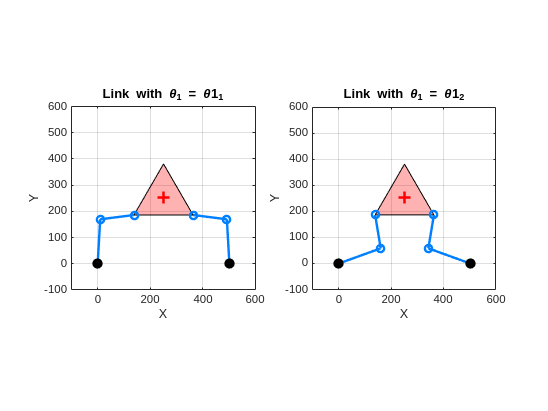


%plots
figure;

%axis limits
x_lim = [-100, 600];
y_lim = [-100, 600];

% Subplot 1: Link with theta1_1
subplot(1, 2, 1); % 1 row, 2 columns, first subplot
fill(p_rotated.Vertices(:, 1), p_rotated.Vertices(:, 2), 'red', 'FaceAlpha', 0.3);
hold on;
plot(x_c_val, y_c_val, 'r+', 'MarkerSize', 10, 'LineWidth', 2); % Plot the center point
plot([0, x_end1], [0, y_end1], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 1-1
plot([x_pp_end1, PP1_val(1,1)], [y_pp_end1, PP1_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 1-2
plot([r_base*sqrt(3), x2_end1], [0, y2_end1], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-1
plot([x_pp2_end1, PP2_val(1,1)*-1], [y_pp2_end1, PP2_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-2
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
plot(r_base*sqrt(3), 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
title('Link with \theta_1 = \theta1_1');
xlabel('X');
ylabel('Y');
axis equal;
xlim(x_lim);
ylim(y_lim);
grid on;

% Subplot 2: Link with theta1_2
subplot(1, 2, 2); % 1 row, 2 columns, second subplot
fill(p_rotated.Vertices(:, 1), p_rotated.Vertices(:, 2), 'red', 'FaceAlpha', 0.3);
hold on;
plot(x_c_val, y_c_val, 'r+', 'MarkerSize', 10, 'LineWidth', 2); % Plot the center point
plot([0, x_end2], [0, y_end2], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 1
plot([x_pp_end2, PP1_val(1,1)], [y_pp_end2, PP1_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2
plot([r_base*sqrt(3), x2_end2], [0, y2_end2], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-1
plot([x_pp2_end2, PP2_val(1,1)*-1], [y_pp2_end2, PP2_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-2
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
plot(r_base*sqrt(3), 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
title('Link with \theta_1 = \theta1_2');
xlabel('X');
ylabel('Y');
axis equal;
xlim(x_lim);
ylim(y_lim);
grid on;

%test 
double([x_pp_end1 y_pp_end1])

ans =     9.6051  169.7284


double(subs(M1, [S theta1], [S_val theta1_1])')

ans =     9.6051  169.7284         0



double([x_pp2_end1 y_pp2_end1])

ans =   492.6897  169.7284


double(subs(M2, [S theta2], [S_val theta2_1])')

ans =   492.6897  169.7284         0
